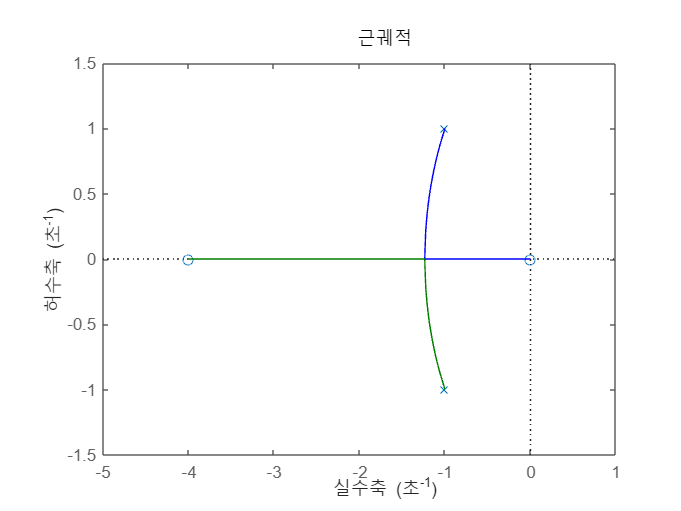

% E 7.1
clear all;

% (a)
syms s K
Ls = K*s*(s+4)/(s^2 + 2*s + 2);
[n, d] = numden(Ls/K);
num = sym2poly(n);
den = sym2poly(d);
sys = tf([num], [den]);
figure();
rlocus(sys);


% (b)
syms K s;
eqn_s = 1 + K*s*(s+4)/(s^2 + 2*s+2) == 0;
s = solve(eqn_s,s);

assume(K,"positive");
eqn_K= s(1) == s(2);
K1 = solve(eqn_K,K);
clear K;

K = K1

$$K = \frac{\sqrt{5}}{4}-\frac{1}{4}$$


% (c)
syms s;
s = solve(1 + K*s*(s+4)/(s^2 + 2*s+2) == 0,s)

$$s = -\frac{2\,\left(\sqrt{5}+1\right)}{\sqrt{5}+3}$$


% (d)
syms s;
G = simplify((K*s*(s+4)/(s^2 + 2*s+2))/(1 + K*s*(s+4)/(s^2 + 2*s+2)))

$$G = \frac{s\,\left(\sqrt{5}-1\right)\,\left(s+4\right)}{4\,s+4\,\sqrt{5}\,s+\sqrt{5}\,s^{2}+3\,s^{2}+8}$$

Ts = 3.2361

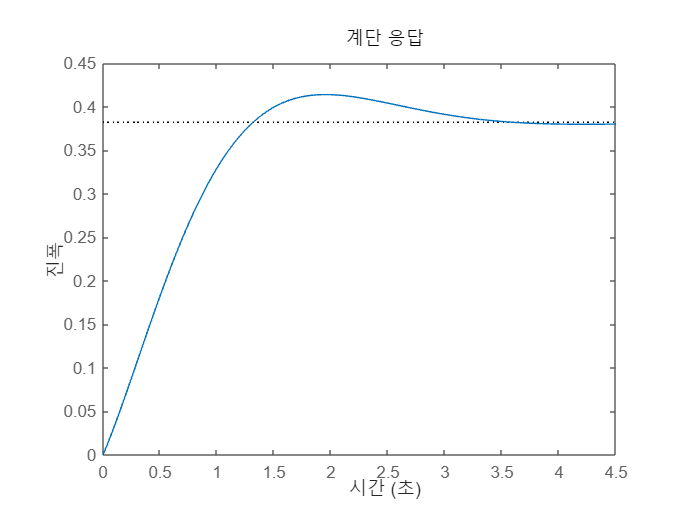

PO = 8.3213

Ts = 3.0644


omega = sqrt(8/(sqrt(5)+3)); % 궤적의 교차점
zeta = ((4+4*sqrt(5))/(2*(sqrt(5)+3)*omega));
Ts = 4/(omega*zeta) % 단위 [s]